siibra = Siibra();

siibra.atlases

ans = 4×2 table
                             Name                                Atlas  
    _______________________________________________________    _________

    {'Multilevel Human Atlas'                             }    1×1 Atlas
    {'Monkey Atlas (pre-release)'                         }    1×1 Atlas
    {'Allen Mouse Common Coordinate Framework v3'         }    1×1 Atlas
    {'Waxholm Space atlas of the Sprague Dawley rat brain'}    1×1 Atlas


human_atlas = siibra.atlases.Atlas(1);
human_atlas.Parcellations

ans = 15×2 table
                       Name                         Parcellation  
    __________________________________________    ________________

    "Julich-Brain Cytoarchitectonic Maps 2.9"     1×1 Parcellation
    "Julich-Brain Cytoarchitectonic Maps 2.5"     1×1 Parcellation
    "Julich-Brain Cytoarchitectonic Maps 1.18"    1×1 Parcellation
    "Short Fiber Bundles - HCP"                   1×1 Parcellation
    "Long White Matter Bundles"                   1×1 Parcellation
    "Superficial Fibre Bundles"                   1×1 Parcellation
    "BigBrain Isocortex"                          1×1 Parcellation
    "BigBrain Cortical Layers"                    1×1 Parcellation
    "DiFuMo 64"                                   1×1 Parcellation
    "DiFuMo 128"                                  1×1 Parcellation
    "DiFuMo 256"                                  1×1 Parcellation
    "DiFuMo 512"                           

julich_parcellations = contains(human_atlas.Parcellations.Name, 'Julich');
human_atlas.Parcellations(julich_parcellations, :)

ans = 3×2 table
                       Name                         Parcellation  
    __________________________________________    ________________

    "Julich-Brain Cytoarchitectonic Maps 2.9"     1×1 Parcellation
    "Julich-Brain Cytoarchitectonic Maps 2.5"     1×1 Parcellation
    "Julich-Brain Cytoarchitectonic Maps 1.18"    1×1 Parcellation


human_atlas.Spaces

ans = 4×2 table
              Name                Space  
    ________________________    _________

    "MNI152 2009c nonl asym"    1×1 Space
    "MNI Colin 27"              1×1 Space
    "Big Brain"                 1×1 Space
    "fsaverage"                 1×1 Space


template = human_atlas.Spaces.Space(4)

template =   Space with properties:

             ID: 'minds/core/referencespace/v1.0.0/tmp-fsaverage'
           Name: 'fsaverage'
    TemplateURL: 'https://siibra-api-latest.apps-dev.hbp.eu/v1_0/atlases/juelich%2Fiav%2Fatlas%2Fv1.0.0%2F1/spaces/minds%2Fcore%2Freferencespace%2Fv1.0.0%2Ftmp-fsaverage/templates'
         Format: 'gii'
     VolumeType: 'surface'
        AtlasId: 'juelich/iav/atlas/v1.0.0/1'


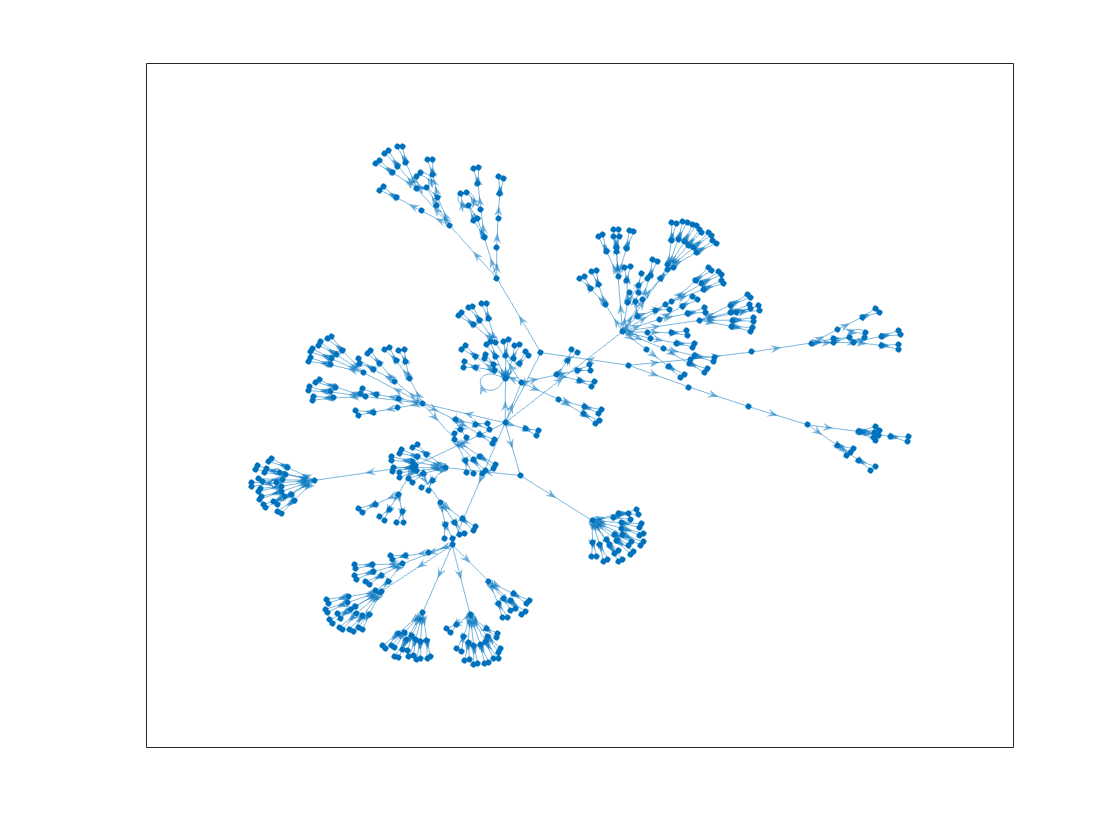

parcellation = human_atlas.getParcellation('Julich-Brain Cytoarchitectonic Maps 2.9');
plot(parcellation.Graph, 'Layout','force')

parcellation

parcellation =   Parcellation with properties:

             Id: 'minds/core/parcellationatlas/v1.0.0/94c1125b-b87e-45e4-901c-00daee7f2579-290'
           Name: 'Julich-Brain Cytoarchitectonic Maps 2.9'
        AtlasId: 'juelich/iav/atlas/v1.0.0/1'
       Modality: 'cytoarchitecture'
    Description: []
          Graph: [1×1 digraph]
         Spaces: []


region = parcellation.getRegion("Ch 123 (Basal Forebrain) left");
region.Spaces.Name

ans = 2×1 string array
    "Probabilistic map of Ch 123 (Basal Forebrain)"
    "Probabilistic map of Ch 123 (Basal Forebrain)"
